**2. The Bouncing Ball (Projectile Motion)**

MATLAB is built for physics. This scenario lets you visualize how an object moves through space using gravity.

- **The Goal:** Calculate the trajectory of a ball thrown at a specific angle and velocity. Use the standard kinematic equations

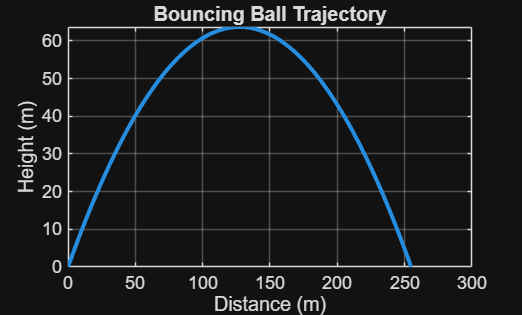

% The Bouncing Ball (Projectile Motion) 
clear; clc;

% 1. Define Constants
g = 9.81;          % Gravity (m/s^2)
v0 = 50;           % Initial velocity (m/s)
theta = 45;        % Launch angle (degrees)
theta_rad = deg2rad(theta); % Convert to radians for sin/cos

% 2. Calculate Time of Flight
% Formula: t_final = (2 * v0 * sin(theta)) / g
t_final = (2 * v0 * sin(theta_rad)) / g;
t = linspace(0, t_final, 100); % Create 100 points from start to finish

% 3. Calculate X and Y coordinates
x = v0 * cos(theta_rad) * t; 
y = v0 * sin(theta_rad) * t - 0.5 * g * t.^2;

% 4. Visualize the result
plot(x, y, 'LineWidth', 2) % Plots the x and y values on the graph 
grid on % Puts a grid on the graph 
xlabel('Distance (m)') % Labels the x value distance
ylabel('Height (m)') % Labels the y axis height
title('Bouncing Ball Trajectory') % Provides a title for the graph 